# Raw signal dimensionality

Load in various data sets from the same excitation light and compute the dimensionality using svd or pca.

ieInit;
wave = 500:700;
[T,dataDir] = oeDatabaseCreate;

## Tongue: excitation 415

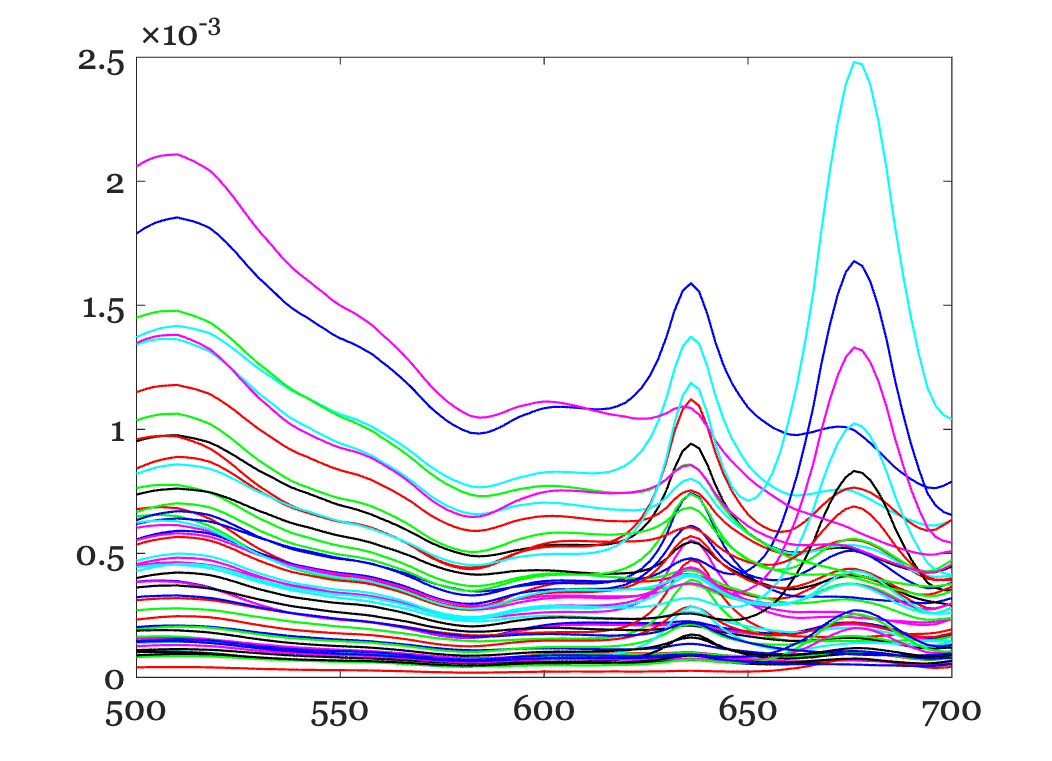

files415 = ieTableGet(T,...
    'substrate','tongue',...
    'e wave',415,...
    'return','files');
data = zeros(numel(wave),numel(files415));
for ii=1:numel(files415)
    data(:,ii) = ieReadSpectra(fullfile(dataDir,files415(ii)),wave);
end

ieNewGraphWin;
plot(wave,data);

## Perform PCA

[coeff, score, latent, tsquared, explained] = pca(data);

% Analyze the 'latent' (eigenvalues) and 'explained' (explained variance ratio)
% to determine dimensionality.

% Plot the explained variance
% ieNewGraphWin;
% plot(explained, 'o-');
% xlabel('Principal Component Index');
% ylabel('Explained Variance (%)');
% title('Explained Variance by Principal Components');

% Thresholding (90% explained variance)
cumulativeExplained = cumsum(explained);
dimensionality = find(cumulativeExplained >= 99.5, 1, 'first');

fprintf('Estimated dimensionality: %d\n', dimensionality);

Estimated dimensionality: 3


## Tongue all excitations

Read and perform PCA

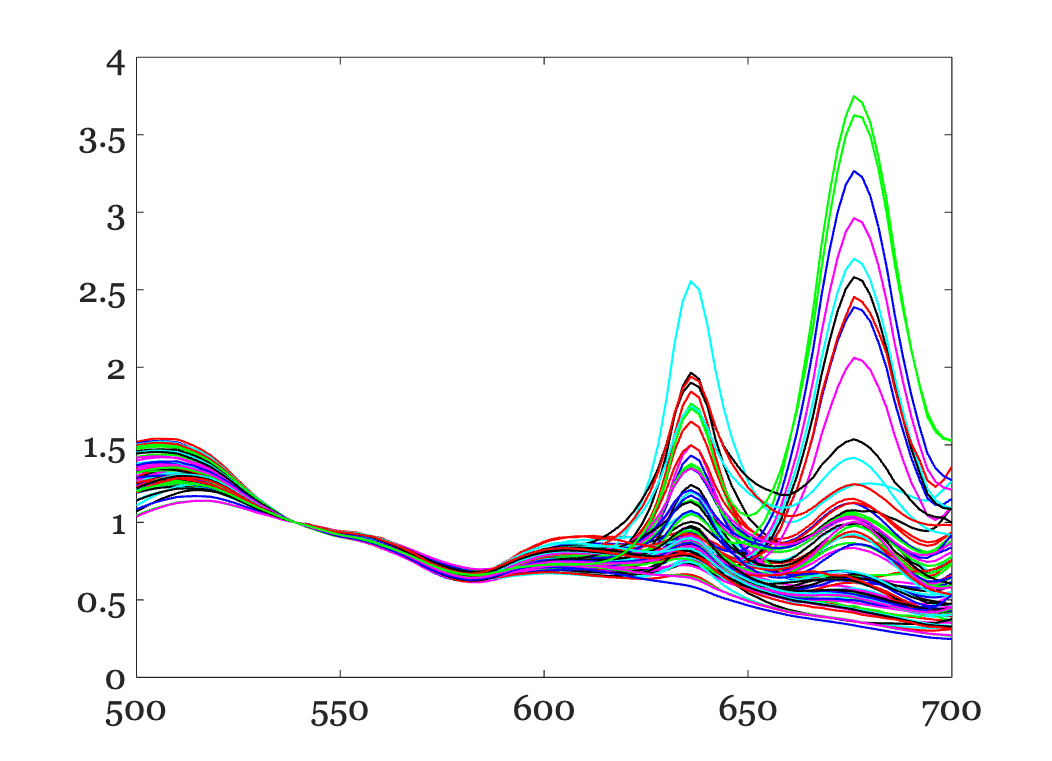

filesAll = ieTableGet(T,...
    'substrate','tongue',...
    'return','files');
data = zeros(numel(wave),numel(filesAll));
for ii=1:numel(filesAll)
    data(:,ii) = ieReadSpectra(fullfile(dataDir,filesAll(ii)),wave);
    data(:,ii) = data(:,ii)/data(40,ii);
end

ieNewGraphWin;
plot(wave,data);

## SVD method

% Perform SVD
[U, S, V] = svd(data, 'econ');
eigenvalues = diag(S).^2;
totalVariance = sum(eigenvalues);
explainedVarianceRatio = eigenvalues / totalVariance;

% Thresholding (90% explained variance)
cumulativeVariance = cumsum(explainedVarianceRatio);
dimensionality = find(cumulativeVariance >= 0.995, 1, 'first');

fprintf('Estimated dimensionality: %d\n', dimensionality);

Estimated dimensionality: 3


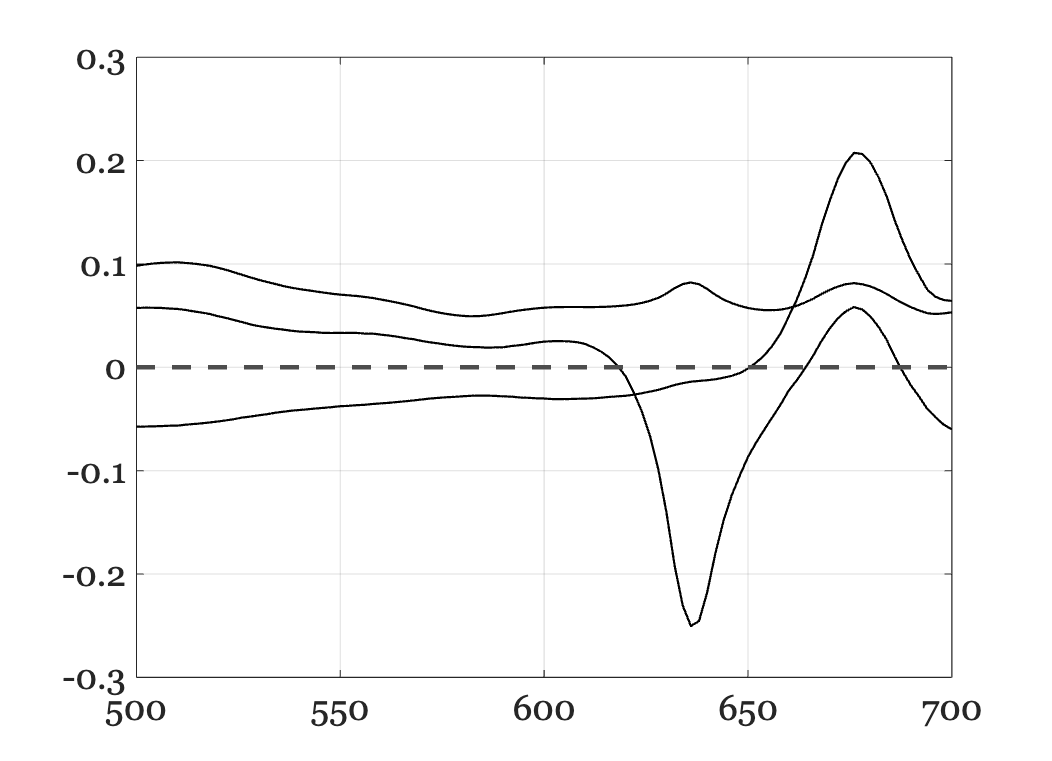


% ieNewGraphWin;
% semilogy(explainedVarianceRatio, 'o-');
% ylim([10^-4 1]); grid on;
% xlabel('Principal Component Index');
% ylabel('Explained Variance Ratio');
% title('Explained Variance Ratio by Principal Components');

ndim = 3;
% The mean and basis vectors
ieNewGraphWin;
plot(wave,-1*U(:,1:ndim),'k-');
grid on;
xaxisLine;

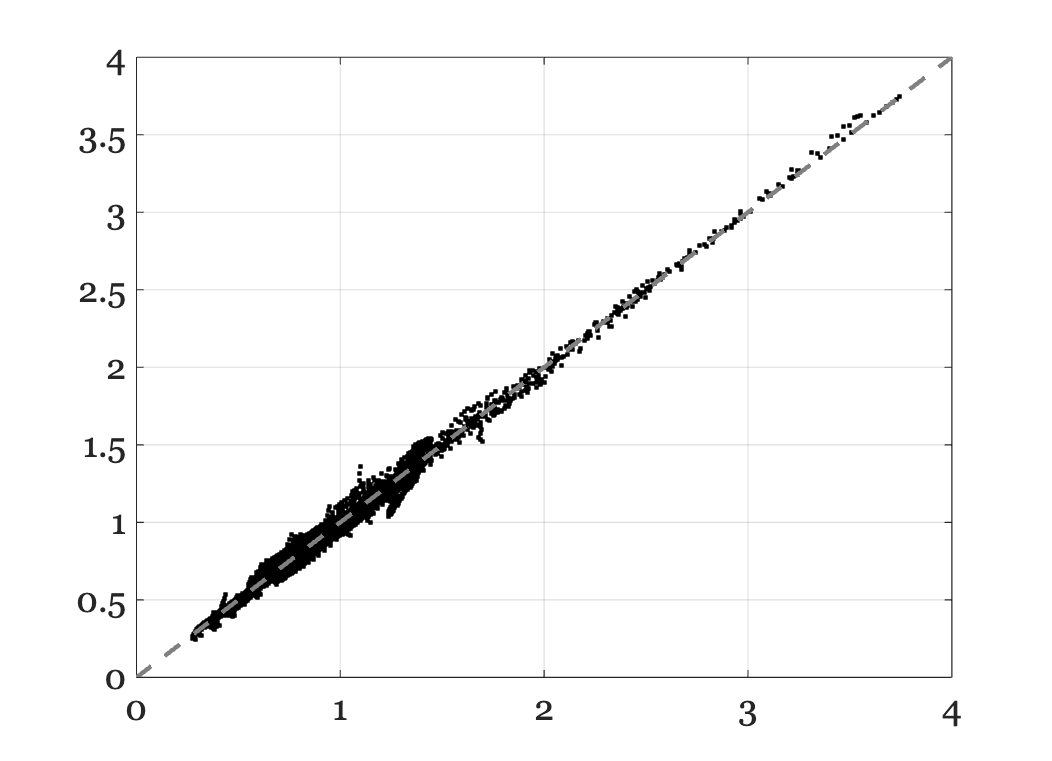


wgts = U(:,1:ndim)'*data;
est = U(:,1:ndim)*wgts;
plot(est(:),data(:),'k.');
identityLine;
grid on;

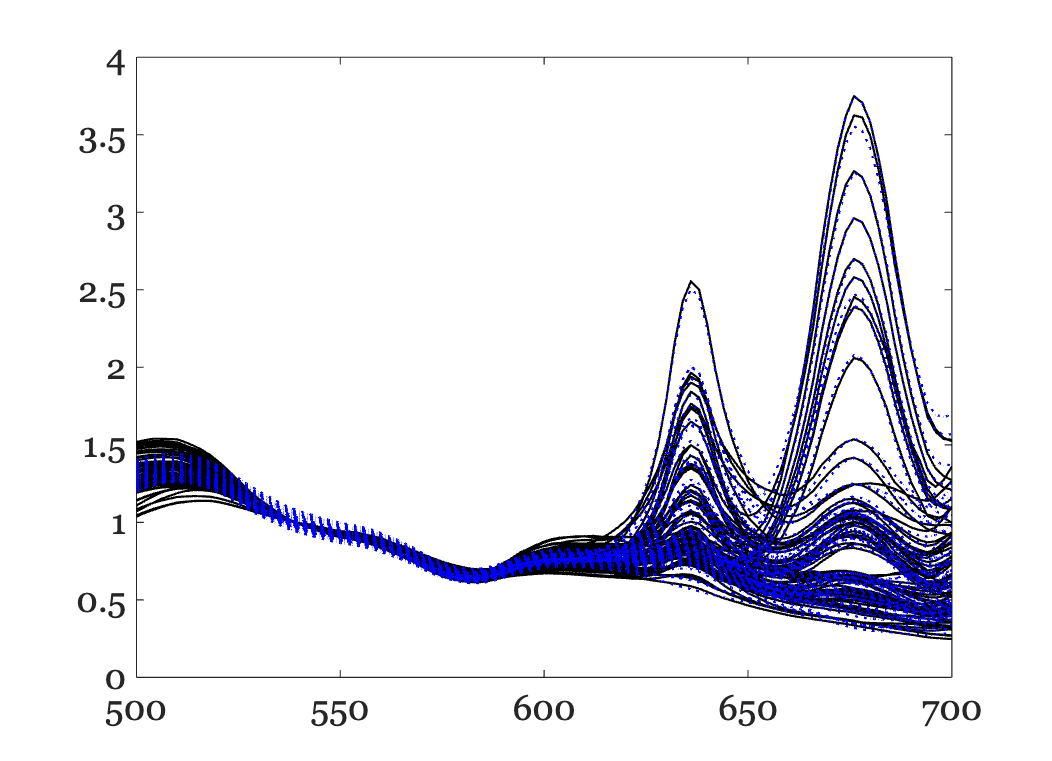


ieNewGraphWin;
plot(wave,data,'k-'); hold on;
plot(wave,est,'b:');


% How well does collagen-blood and FAD and Porphyrin fit the basis, U?
% Or the other way around?

## Lip

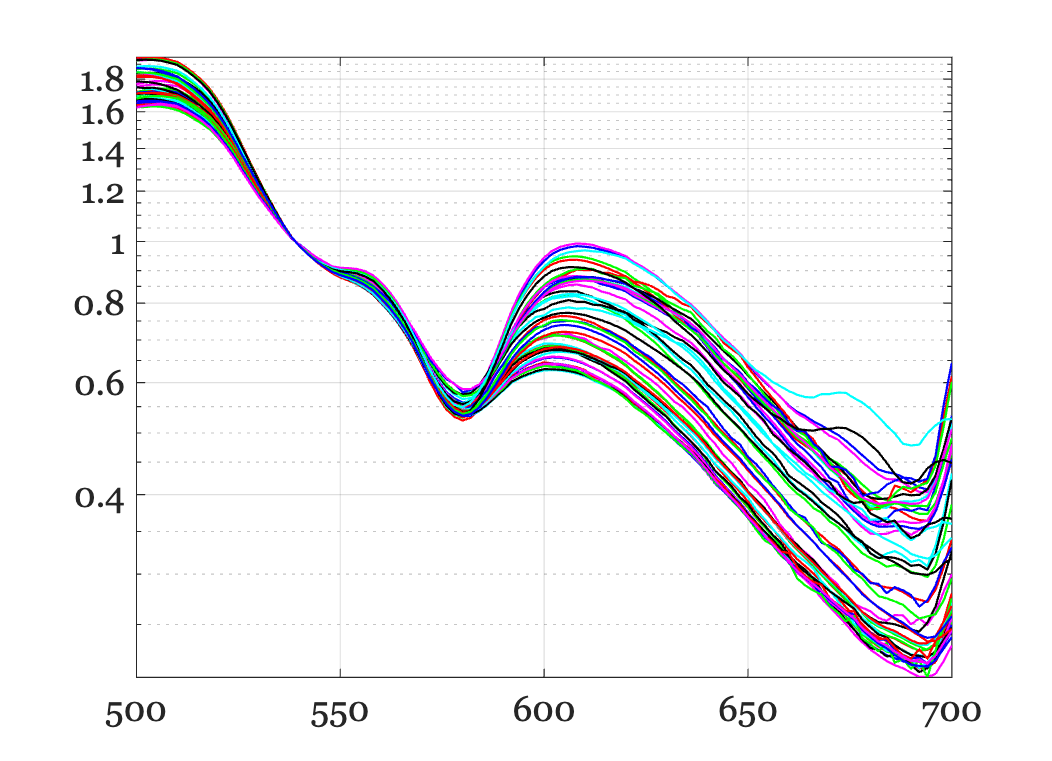

filesAll = ieTableGet(T,...
    'substrate','lip',...
    'e wave',415, ...
    'return','files');
data = zeros(numel(wave),numel(filesAll));
for ii=1:numel(filesAll)
    data(:,ii) = ieReadSpectra(fullfile(dataDir,filesAll(ii)),wave);
    data(:,ii) = data(:,ii)/data(40,ii);
end

ieFigure;
semilogy(wave,data); grid on;


[U, S, V] = svd(data, 'econ');
eigenvalues = diag(S).^2;
totalVariance = sum(eigenvalues);
explainedVarianceRatio = eigenvalues / totalVariance;

% Thresholding (90% explained variance)
cumulativeVariance = cumsum(explainedVarianceRatio);
dimensionality = find(cumulativeVariance >= 0.999, 1, 'first');

fprintf('Estimated dimensionality: %d\n', dimensionality);

Estimated dimensionality: 2


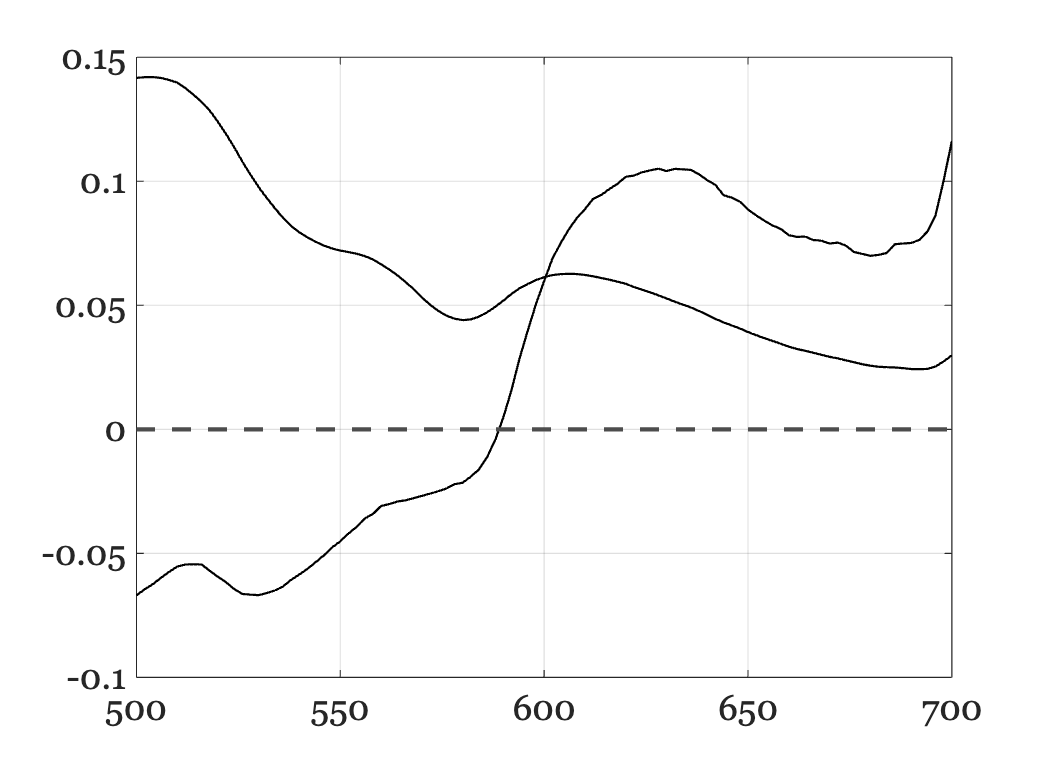


ndim = 2;

ieNewGraphWin;
plot(wave,-1*U(:,1:ndim),'k-');
grid on;
xaxisLine;

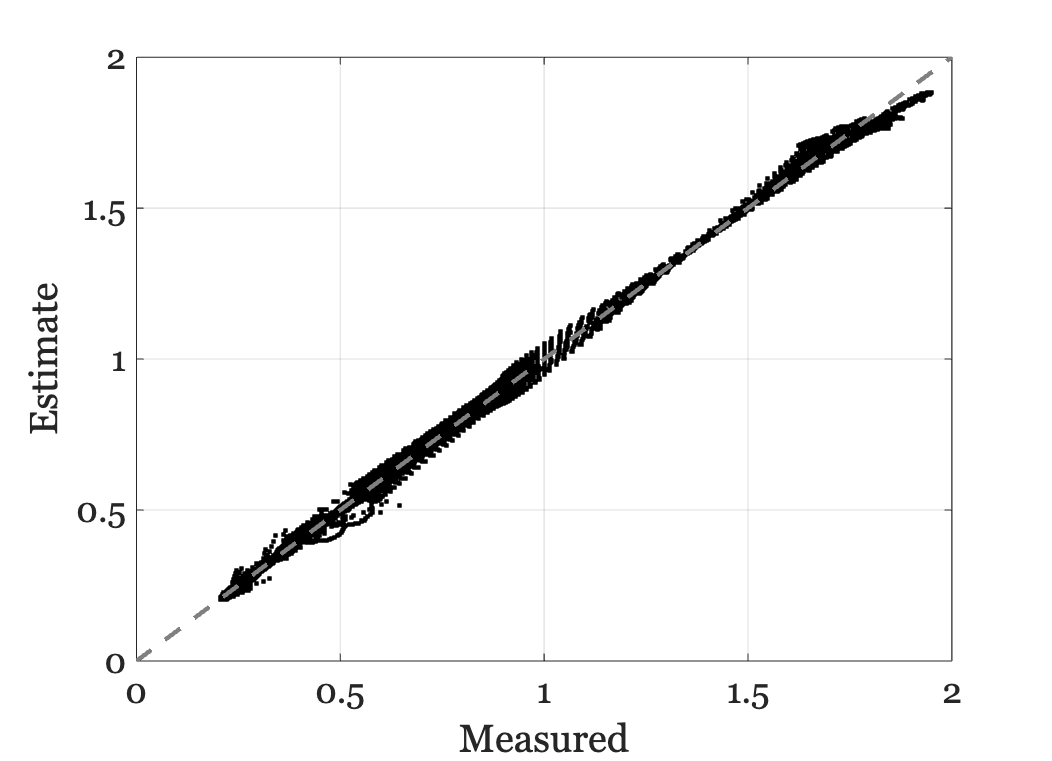


wgts = U(:,1:ndim)'*data;
est = U(:,1:ndim)*wgts;
plot(data(:),est(:),'k.');
identityLine;
grid on; xlabel('Measured'); ylabel('Estimate');

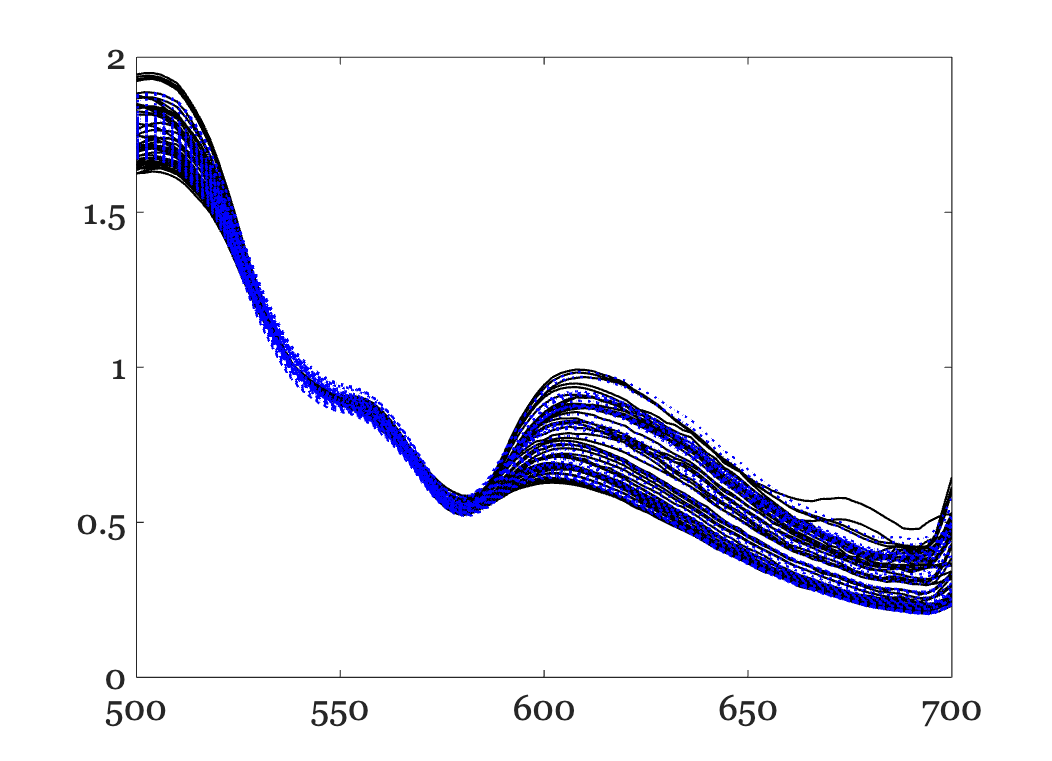


ieNewGraphWin;
plot(wave,data,'k-'); hold on;
plot(wave,est,'b:');


% How well does collagen-blood and FAD and Porphyrin fit the basis, U?
% Or the other way around?
